# DIABLO ROS2 -- MATLAB SDK 

## matlab安装ROS Toolbox

matlab安装ROS Toolbox 

[ROS Toolbox](https://ww2.mathworks.cn/help/ros/index.html?s_tid=CRUX_lftnav)

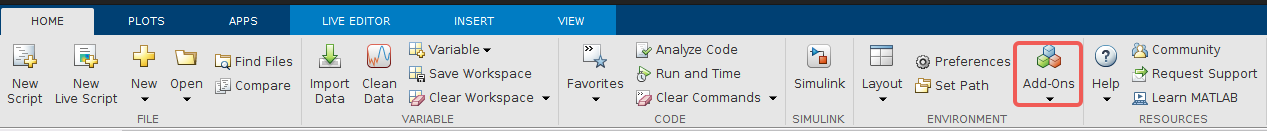

点击Add-ons，搜索ROS Toolbox，点击Install即可

## 配置

### MATLAB ROS2 自定义消息

关于MATLAB ROS2 自定义消息，您可以查看reference/ROS2CustomMessagesExample.mlx。

将[diablo_ros2](https://github.com/DDTRobot/diablo_ros2)中定义的消息加入到/custom文件夹中（文件结构如下所示）

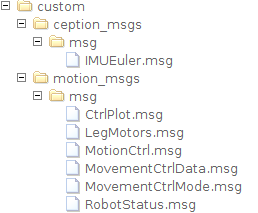

运行 **diablo_ros2genmsg.m **来指定自定义消息文件的文件夹路径，该脚本使用`ros2genmsg为MATLAB`创建自定义消息。

调用`ros2 msg list`以验证新自定义消息的创建。

ros2 msg list

### 

### 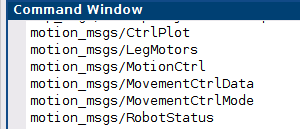

### 配置ROS_DOMAIN_ID

需要保证主机与机器人连接同一局域网，并且domain id相同。检查**机器人**的domain id，打开**终端**，输入 

echo $ROS_DOMAIN_ID

在matlab **Command Window **检查主机的ros domain id

getenv("ROS_DOMAIN_ID")

如果两者不同可以使用setenv命令设置domain ID（以25为例）

setenv("ROS_DOMAIN_ID","25")

`ROS_DOMAIN_ID配置完毕`

### `启动diablo MATLAB SDK`

`默认您已经完成了准备工作，具体请参考`[diablo_ros2](https://github.com/DDTRobot/diablo_ros2)

`机器人``使用如下指令启动diablo sdk`

ros2 run diablo_ctrl diablo_ctrl_node

`您可以使用ros2 node list`来查看当前domain ID 中的节点

ros2 node list

`（您可以使用下面指令重置ROS_DOMAIN_ID为默认` ）

setenv("ROS_DOMAIN_ID","")

现在您可以matlab启动**diablo_teleop_ctrl.m**使用键盘控制diablo

***注意：***该例程需要使用**Esc**按键退出虚拟遥控器

% w：控制机器人向前移动。 （-1.0~+1.0米/秒）; （-1.6~+1.6米/秒Low-speed mode::High-speed mode::
% s：控制机器人向后移动。 （-1.0~+1.0米/秒）; （-1.6~+1.6米/秒Low-speed mode::High-speed mode::
% a：控制机器人左转。 （-5.0~+5.0 弧度/秒）Arbitrarily mode::
% d：控制机器人右转。 （-5.0~+5.0 弧度/秒）Arbitrarily mode::
% q：控制机器人向左倾斜。 （-0.2~+0.2弧度/秒）Standing mode::
% e：控制机器人向右倾斜。 （-0.2~+0.2弧度/秒）Standing mode::
% r：将机身倾斜角度调整为水平。Standing mode:
% z：将机器人切换到站立模式。
% x：将机器人切换到爬行模式。
% h：站立模式下的最小高度。Position mode
% k：站立模式下的中等高度。Position mode
% j：站立模式下的最大高度。Position mode
% u：控制机器人上仰。Position mode
% i：将机身调整为水平。Position mode
% o：控制机器人下仰。Position mode
% f：太空步。dance mode
% g：太空步结束。dance mode
% Esc：退出虚拟遥控器。

***注意***

您可以使用clear命令来清理所有publisher，subscriber和node。

 clear
 % diablo_ception.m
 % clear ImuSub MotorSub BatterySub matlab_diablo_ception_node; 
 
 % diablo_ception_show.m
 % clear ImuSub MotorSub BatterySub matlab_diablo_ception_show_node;

## MATLAB ROS2节点目录

**1.diablo_ception.m（diablo_ception_show.m ）**使用matlab_diablo_ception_node（matlab_diablo_ception_show_node）节点订阅话题，并读取IMU，各个关节电机和轮毂电机以及电池信息，将其打印在command window（图窗）中。（使用clear指令来清理subscriber以停止打印）

**2.diablo_teleop_node.m **使用matlab_diablo_teleop_node节点发布话题，使用键盘控制机器人运动。

**3.diablo_interact.m **使用matlab_diablo_interact_node节点订阅和发布话题，实时绘制机器人状态信息以及使用键盘控制机器人运动。

## 参考资料

- 基于串口通信的 `DIABLO` 机器人二次开发控制接口[diablo_ros2](https://github.com/DDTRobot/diablo_ros2)

- 连接到 ROS 2 网络并建立通信 [Connect to ROS 2 Network and Establish Communication](https://ww2.mathworks.cn/help/ros/gs/ros2-nodes.html)

- 按版本发布的与 MATLAB 产品兼容的 Python 版本 [Versions of Python Compatible with MATLAB Products by Release](https://ww2.mathworks.cn/support/requirements/python-compatibility.html)